1.

A

p = @(x) polyval([1 0 0 0 0 -1], x);
X=[-2 -1 0 1 2 3];
Y = p(X);
b=linterp(X,Y,-3)

b = -244.0000

p(-3)

ans = -244

B

Lagrange interpolation will fail if the points are not distinct

C

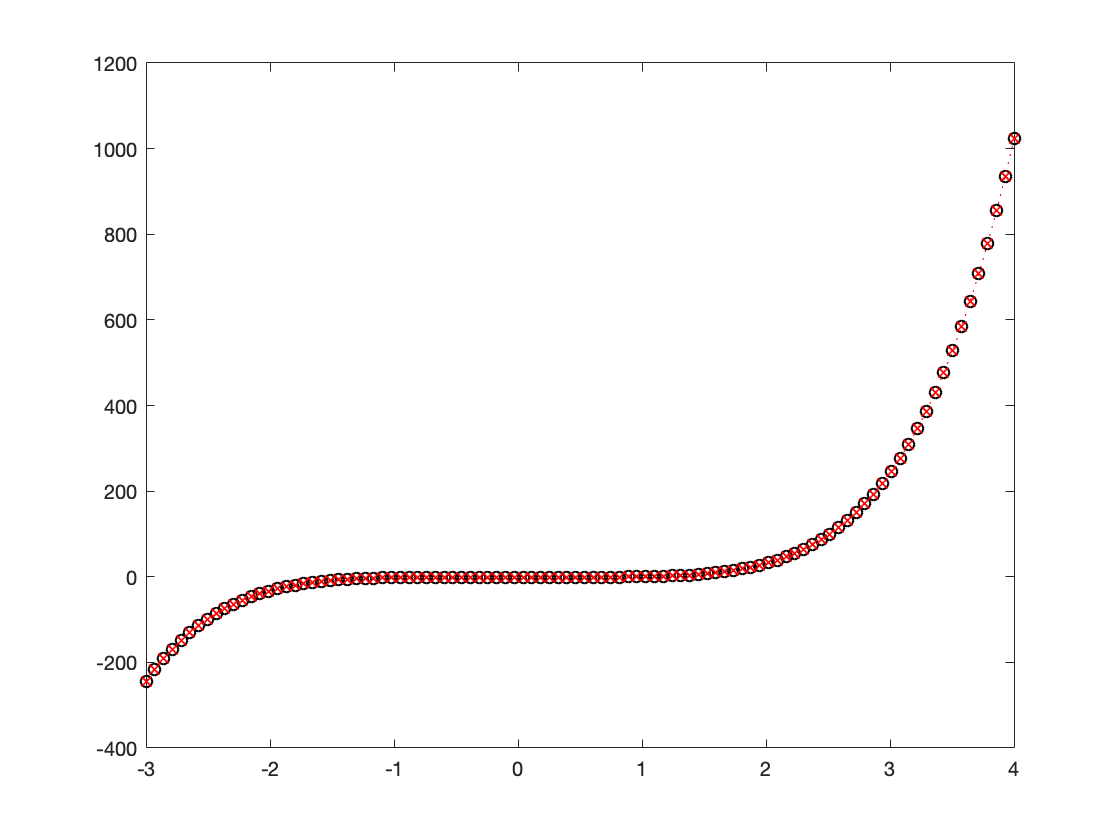

x = linspace(min(X)-1, max(X)+1, 100);
plot(x, p(x),'ko:', x, linterp(X, Y, x),'rx:');

2.

X=[1,2,3,4];
mypoly(X)

ans =      1   -10    35   -50    24


poly(X)

ans =      1   -10    35   -50    24


Helper Functions

function y = linterp(X,Y,x)
n=size(X,2);
L=ones(n,size(x,2));
   for i=1:n
      for j=1:n
         if (i~=j)
            L(i,:)=L(i,:).*(x-X(j))/(X(i)-X(j));
         end
      end
   end
   y=0;
   for i=1:n
      y=y+Y(i)*L(i,:);
   end
end


function p = mypoly(X)
p=[1,-X(1)];
for i=2:numel(X)
    y=p(numel(p))*-X(i);
    v=p;
    for j=2:numel(p)
        p(j)=p(j)+-X(i)*v(j-1);
    end
    p=[p,y];
end
end